# Strava History Analysis

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

General variables

n_bins = 25;
n_cvpartitions = 10;
def_colors =[ [0, 0.4470, 0.7410];
          	[0.8500, 0.3250, 0.0980];
          	[0.9290, 0.6940, 0.1250];
          	[0.4940, 0.1840, 0.5560];
          	[0.4660, 0.6740, 0.1880];
          	[0.3010, 0.7450, 0.9330];
          	[0.6350, 0.0780, 0.1840]];

## Initialize variables

Load tables

activities_set = readtable('../strava_history/activities.csv')

activities_set = 517×84 table
    ActivityID            ActivityDate                           ActivityName                   ActivityType    ActivityDescription    ElapsedTime    Distance    MaxHeartRate    RelativeEffort     Commute     ActivityGear              Filename               AthleteWeight    BikeWeight    ElapsedTime_1    MovingTime    Distance_1    MaxSpeed    AverageSpeed    ElevationGain    ElevationLoss    ElevationLow    ElevationHigh    MaxGrade    AverageGrade    AveragePositiveGrade    AverageNegativeGrade    

### Transform input data

Ensure that ID is integer (this variable will only be used for mapping to GPX files, not as a predictor)

activities_set.ActivityID = uint64(activities_set.ActivityID);

Create categorical variables

activities_set.ActivityType = categorical(activities_set.ActivityType);
activities_set.ActivityGear = categorical(activities_set.ActivityGear);
activities_set.ActivityGear = fillmissing(activities_set.ActivityGear, "constant", "No Data");

Divide Date into day of the year / year

aux = split(activities_set.ActivityDate,',');

activities_set.DayofYear = day(datetime(datenum(aux(:,1),'mmmdd'), ConvertFrom='datenum'), 'dayofyear');
activities_set.Year = uint16(str2num(cell2mat(aux(:,2))));

Get paused time

activities_set.PausedTimeRatio = activities_set.ElapsedTime ./ activities_set.MovingTime - 1;

Get net elevation (difference between starting point and destination)

activities_set.ElevationNet = activities_set.ElevationGain - activities_set.ElevationLoss;

Compute total weight

def_AthleteWeight = 70;
def_BikeWeight = 13;
def_LuggageWeight = 7;

activities_set.TotalWeight = fillmissing(activities_set.AthleteWeight, "constant", def_AthleteWeight);
% Add bike weight
idx = activities_set.ActivityType == "Ride";
activities_set.TotalWeight(idx) = activities_set.TotalWeight(idx) + fillmissing(activities_set.BikeWeight(idx), "constant", def_BikeWeight);
% Add luggage weight when doing bikepacking
idx = contains(activities_set.ActivityDescription, "Bikepacking");
activities_set.TotalWeight(idx) = activities_set.TotalWeight(idx) + def_LuggageWeight;

Convert Speed from [m/s] to [km/h]

activities_set.MaxSpeed = 3.6*activities_set.MaxSpeed;
activities_set.AverageSpeed = 3.6*activities_set.AverageSpeed;

Get average ascent meters per kilometer

activities_set.ElevationGainRatio = activities_set.ElevationGain ./ activities_set.Distance;

Compute mean speed from distance and moving time

activities_set.MeanSpeed = 3600*activities_set.Distance ./ activities_set.MovingTime;

### Check correctness

#### Check computed MeanSpeed is similar to AvgSpeed provided

max_test = max(activities_set.AverageSpeed ./ activities_set.MeanSpeed);
min_test = min(activities_set.AverageSpeed ./ activities_set.MeanSpeed);
fprintf(strcat("Max/Min ratio of mean speed: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min ratio of mean speed: 1.0018 / 0.99983

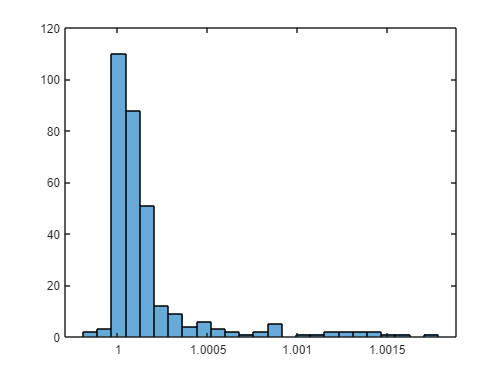

histogram(activities_set.AverageSpeed ./ activities_set.MeanSpeed, n_bins)

#### Check reasonable MeanSpeed

max_test = max(activities_set.MeanSpeed);
min_test = min(activities_set.MeanSpeed);
fprintf(strcat("Max/Min mean speed: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min mean speed: 101.4647 / 0.69058

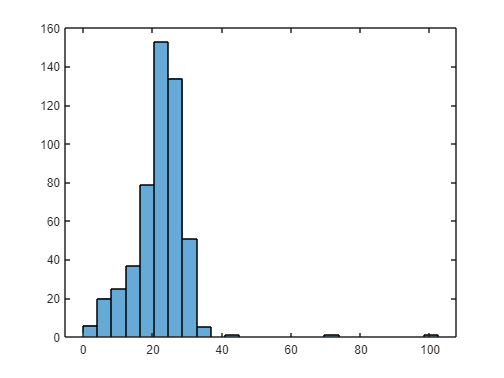

histogram(activities_set.MeanSpeed, n_bins)

Remove Outliers

activities_set(activities_set.MeanSpeed > 40, :) = [];

max_test = max(activities_set.MeanSpeed);
min_test = min(activities_set.MeanSpeed);
fprintf(strcat("Max/Min mean speed: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min mean speed: 34.1903 / 0.69058

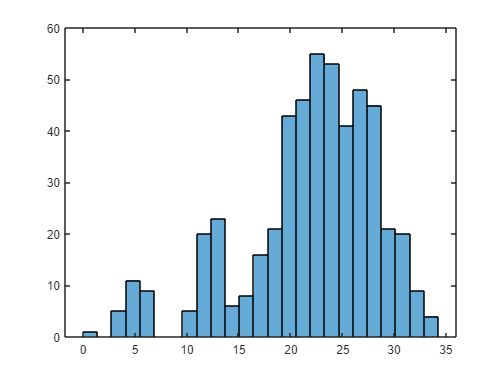

histogram(activities_set.MeanSpeed, n_bins)

#### Check reasonable MaxSpeed

max_test = max(activities_set.MaxSpeed);
min_test = min(activities_set.MaxSpeed);
fprintf(strcat("Max/Min max speed: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min max speed: 153 / 11.88

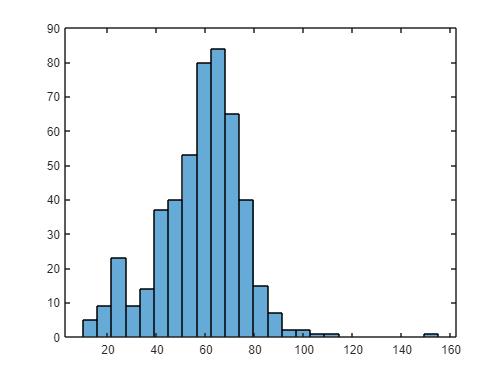

histogram(activities_set.MaxSpeed, n_bins)

Remove outliers

activities_set(activities_set.MaxSpeed > 120, :) = [];

max_test = max(activities_set.MaxSpeed);
min_test = min(activities_set.MaxSpeed);
fprintf(strcat("Max/Min max speed: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min max speed: 110.52 / 11.88

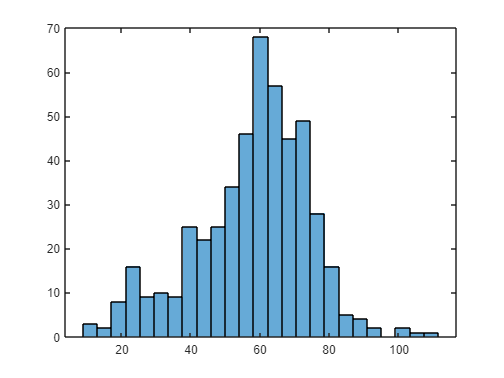

histogram(activities_set.MaxSpeed, n_bins)

#### Check reasonable AverageWatts

max_test = max(activities_set.AverageWatts);
min_test = min(activities_set.AverageWatts);
fprintf(strcat("Max/Min average Power: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min average Power: 485.1785 / 44.3771

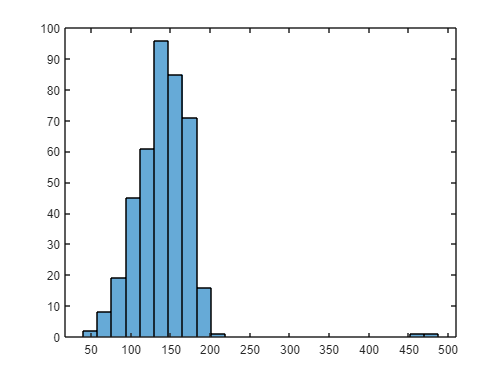

histogram(activities_set.AverageWatts, n_bins)

Remove outliers

activities_set(activities_set.AverageWatts > 300, :) = [];

max_test = max(activities_set.AverageWatts);
min_test = min(activities_set.AverageWatts);
fprintf(strcat("Max/Min average Power: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min average Power: 201.5569 / 44.3771

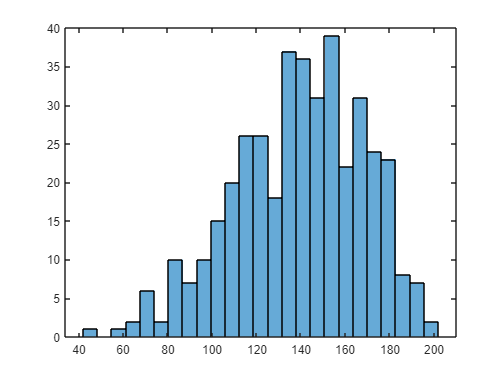

histogram(activities_set.AverageWatts, n_bins)

#### Total weight

max_test = max(activities_set.TotalWeight);
min_test = min(activities_set.TotalWeight);
fprintf(strcat("Max/Min total weight: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min total weight: 89 / 67

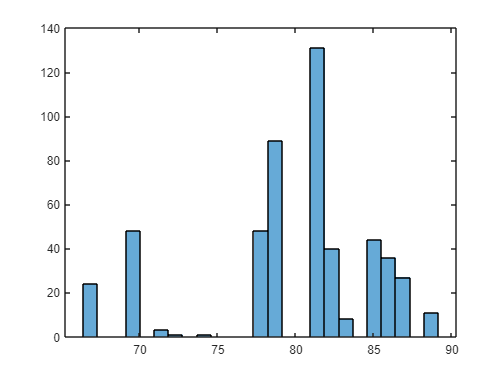

histogram(activities_set.TotalWeight, n_bins)

Ammend outliers (no comma  in athlete Weight)

idx = activities_set.AthleteWeight > 200;
activities_set.TotalWeight(idx) = activities_set.TotalWeight(idx) - 0.9.*activities_set.AthleteWeight(idx);

max_test = max(activities_set.TotalWeight);
min_test = min(activities_set.TotalWeight);
fprintf(strcat("Max/Min total weight: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min total weight: 89 / 67

histogram(activities_set.TotalWeight, n_bins)

### Keep only variables of interest

vars = ["ActivityID", "Year", "DayofYear", "ActivityType", "MovingTime", "PausedTimeRatio", "Distance", ...
        "MeanSpeed", "MaxSpeed", "ElevationGain", "ElevationGainRatio", "ElevationNet", "ElevationHigh", ...
        "TotalWeight", "AverageWatts", "Calories", "ActivityGear"];
dataClean = activities_set(:,vars)

dataClean = 511×17 table
    ActivityID    Year    DayofYear    ActivityType    MovingTime    PausedTimeRatio    Distance    MeanSpeed    MaxSpeed    ElevationGain    ElevationGainRatio    ElevationNet    ElevationHigh    TotalWeight    AverageWatts    Calories    ActivityGear
    __________    ____    _________    ____________    __________    _______________    ________    _________    ________    _____________    __________________    ____________    _____________    _______

Plot histograms of general data once Cleaned

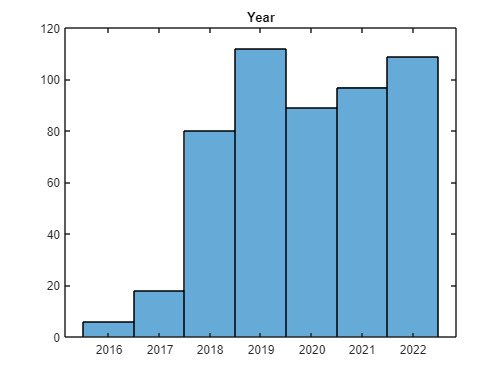

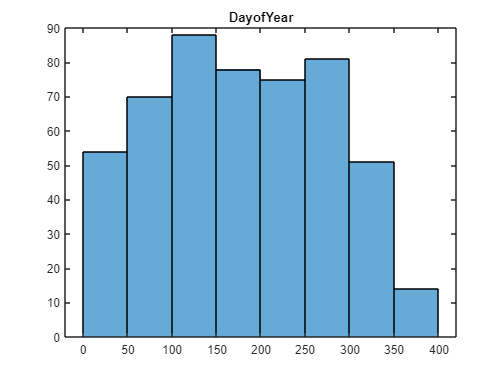

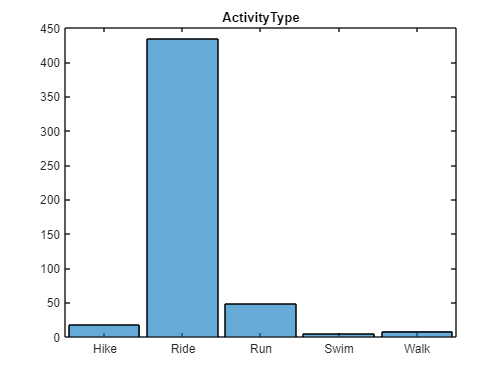

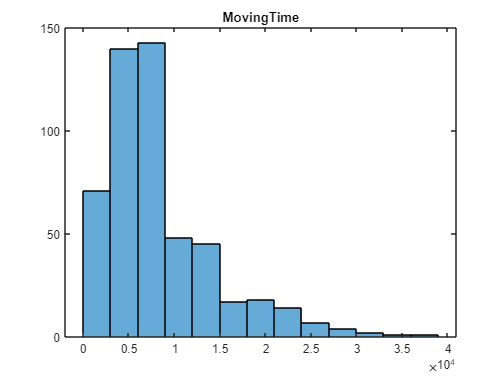

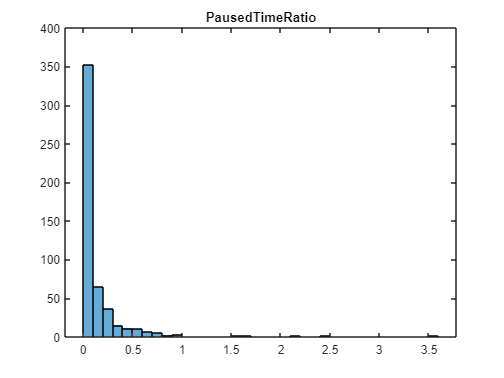

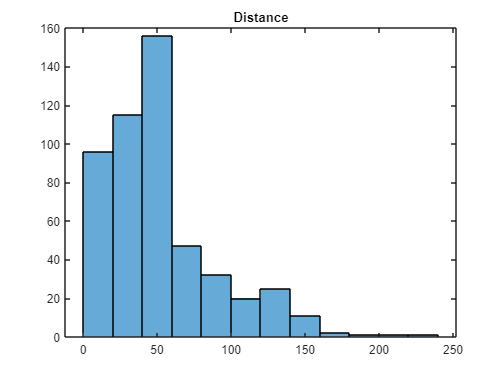

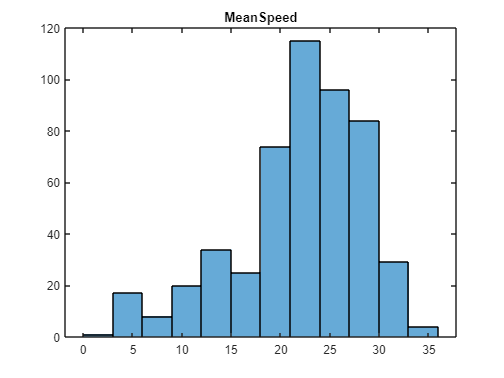

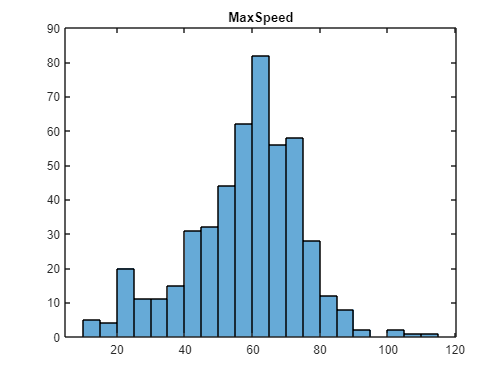

for ii = 2:size(vars,2)
    figure
    if iscategorical(table2array(dataClean(:,vars(ii))))
        histogram(table2array(dataClean(:,vars(ii))))
    else
        histogram(table2array(dataClean(:,vars(ii)), n_bins))
    end
    title(vars(ii))
end

### Activity Type filter: keep only bike rides

cyclingData = dataClean(dataClean.ActivityType == 'Ride', :);
cyclingData = removevars(cyclingData, "ActivityType")

cyclingData = 434×16 table
    ActivityID    Year    DayofYear    MovingTime    PausedTimeRatio    Distance    MeanSpeed    MaxSpeed    ElevationGain    ElevationGainRatio    ElevationNet    ElevationHigh    TotalWeight    AverageWatts    Calories    ActivityGear
    __________    ____    _________    __________    _______________    ________    _________    ________    _____________    __________________    ____________    _____________    ___________    ____________    ______

vars = ["ActivityID", "Year", "DayofYear", "MovingTime", "PausedTimeRatio", "Distance", ...
        "MeanSpeed", "MaxSpeed", "ElevationGain", "ElevationGainRatio", "ElevationNet", "ElevationHigh", ...
        "TotalWeight", "AverageWatts", "Calories", "ActivityGear"];

Plot histograms of Cycling activities Data

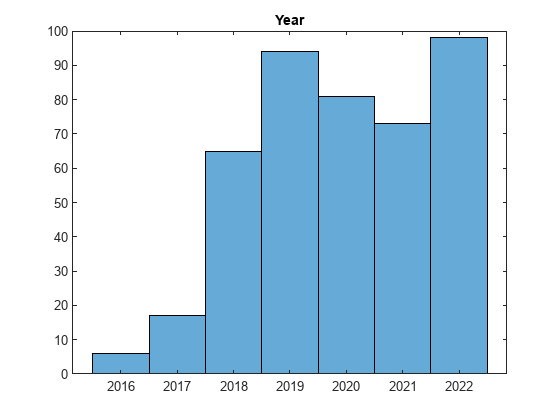

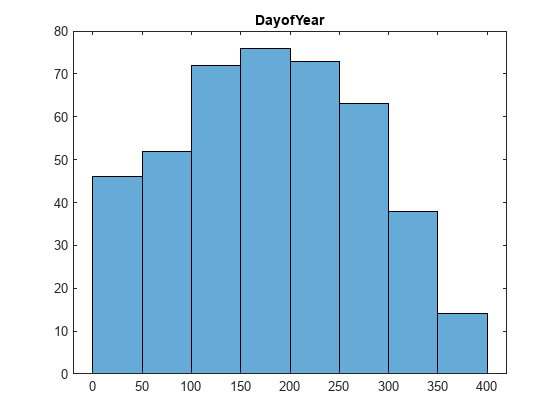

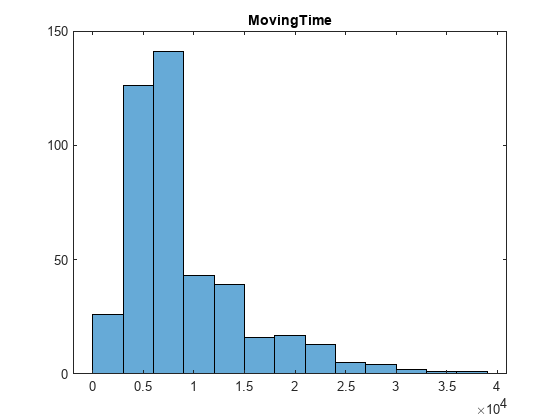

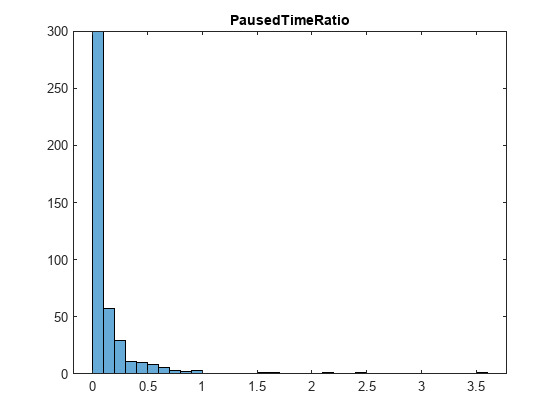

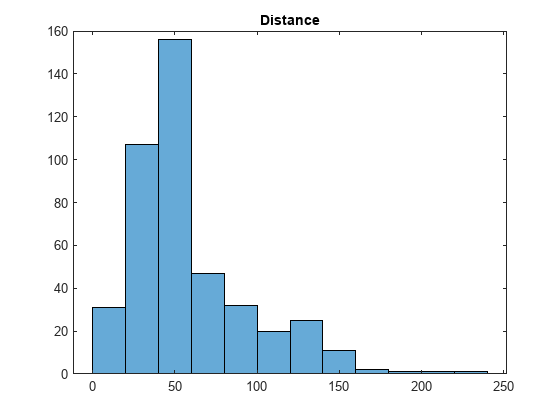

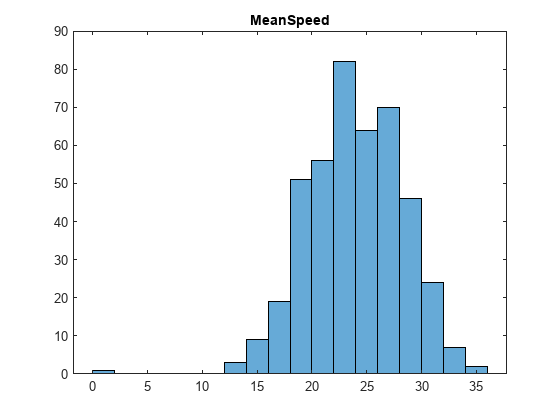

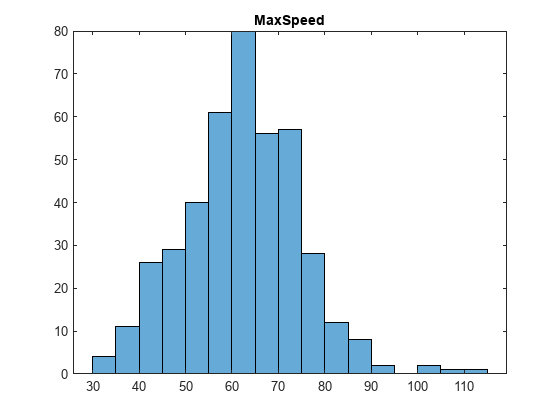

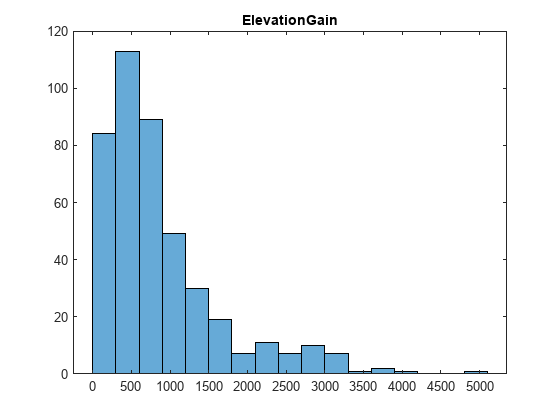

for ii = 2:size(vars,2)
    figure
    if iscategorical(table2array(cyclingData(:,vars(ii))))
        histogram(table2array(cyclingData(:,vars(ii))))
    else
        histogram(table2array(cyclingData(:,vars(ii)), n_bins))
    end
    title(vars(ii))
    saveas(gcf,strcat('Figures/hist_',vars(ii),'.png') )
end

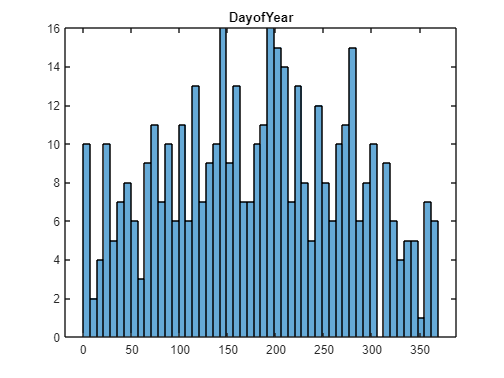

histogram(cyclingData.DayofYear,52)
title("DayofYear")
saveas(gcf,strcat('Figures/hist_DayofYear.png') )

#### Remove outliers of ElevationGainRatio

cyclingData(cyclingData.ElevationGainRatio > 60, :) = [];

max_test = max(cyclingData.ElevationGainRatio);
min_test = min(cyclingData.ElevationGainRatio);
fprintf(strcat("Max/Min Elevation/Distance ratio [m/km]: ",num2str(max_test)," / ",num2str(min_test)))

Max/Min Elevation/Distance ratio [m/km]: 40.1396 / 0

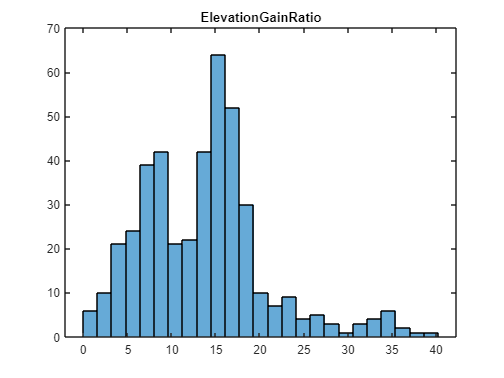

histogram(cyclingData.ElevationGainRatio, n_bins)
title("ElevationGainRatio")
saveas(gcf,strcat('Figures/hist_ElevationGainRatio.png') )

## Save to csv the table to be analysed

writetable(cyclingData,'./data/cyclingData_processed.csv')

## Exploratory Data Analysis

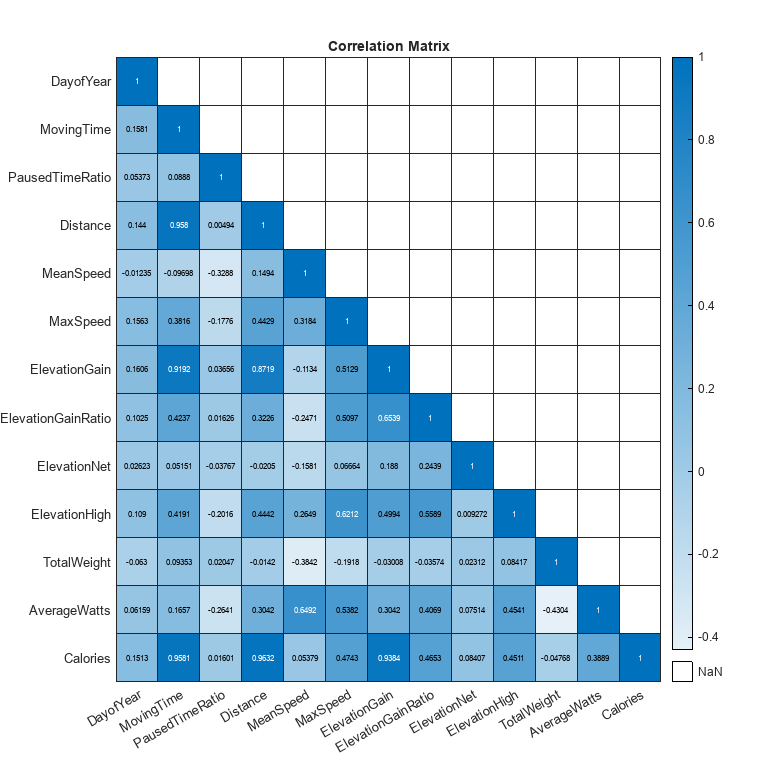

numerical_vars = vars(vars~="ActivityID" &vars~="Year" & vars~="ActivityGear");

X = cyclingData(:,numerical_vars);
xnames = X.Properties.VariableNames;


r = corr(table2array(X),'rows', 'complete');
isupper = logical(triu(ones(size(r)),1));
r(isupper) = NaN;
figure('Position', [0 0 1200 1200])
h = heatmap(r,'MissingDataColor','w');
h.XDisplayLabels = xnames;
h.YDisplayLabels = xnames; 
title("Correlation Matrix")
saveas(gcf,strcat('Figures/corr_matrix.png') )

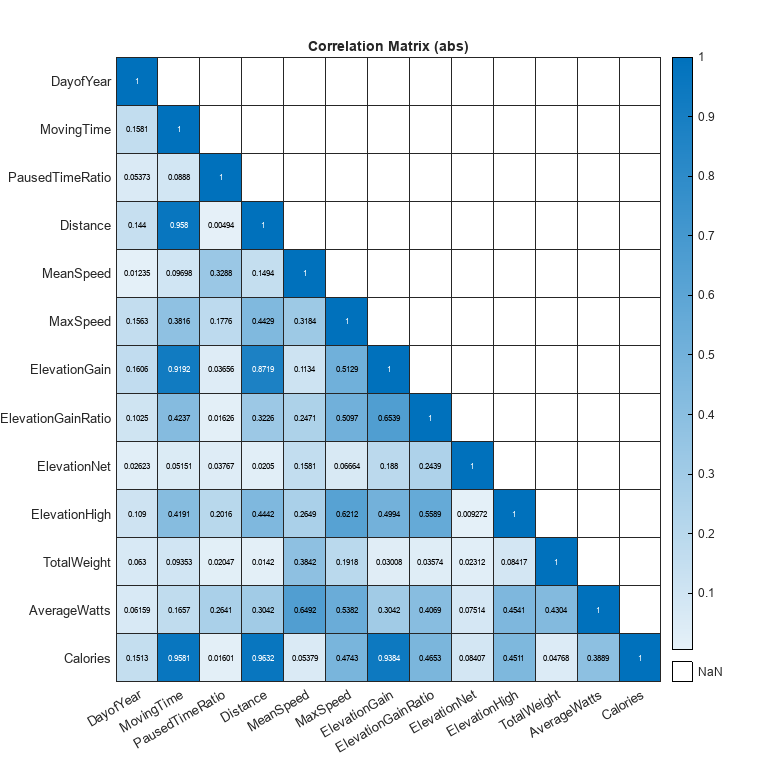


figure('Position', [0 0 1200 1200])
h = heatmap(abs(r),'MissingDataColor','w');
h.XDisplayLabels = xnames;
h.YDisplayLabels = xnames; 
title("Correlation Matrix (abs)")
saveas(gcf,strcat('Figures/corr_matrix_abs.png') )

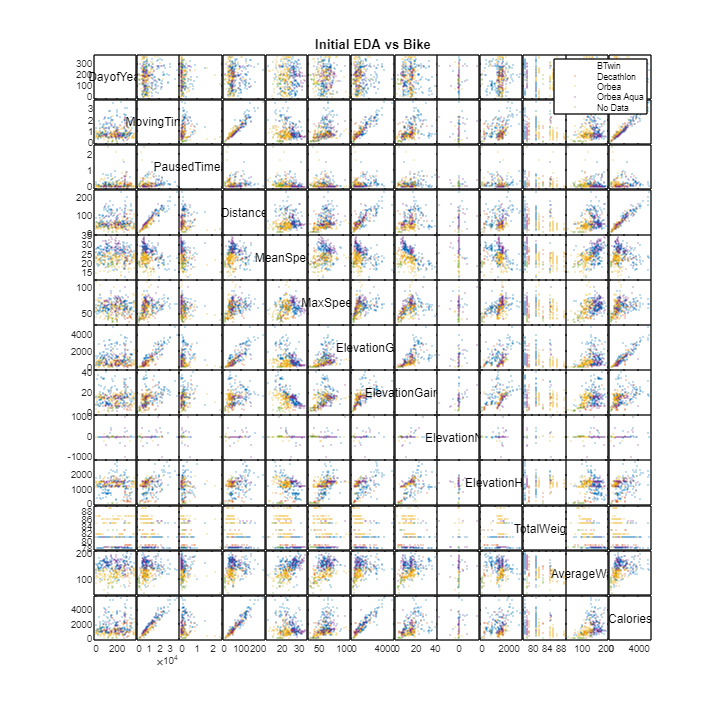


categories = unique(cyclingData.ActivityGear);
color = lines(size(categories));
figure('Position', [0 0 1200 1200])
[h, ax] = gplotmatrix(table2array(X),[],cyclingData.ActivityGear,color,[],[],[],'variable',xnames);
title('Initial EDA vs Bike')
saveas(gcf,strcat('Figures/gplot_bike.png') )

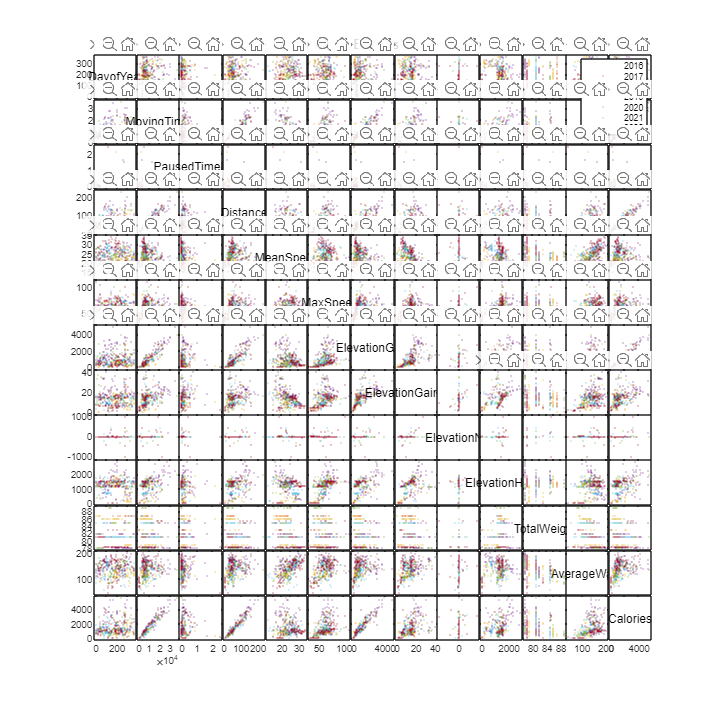

categories = unique(cyclingData.Year);
color = lines(size(categories));
figure('Position', [0 0 1200 1200])
[h, ax] = gplotmatrix(table2array(X),[],cyclingData.Year,color,[],[],[],'variable',xnames);
title('Initial EDA vs Year')
saveas(gcf,strcat('Figures/gplot_year.png') )

## Power and Speed


figure
gscatter(cyclingData.MovingTime./3600, cyclingData.AverageWatts, cyclingData.Year)
legend()
xlabel("Moving time[h]")
ylabel("Avg Power[W]")

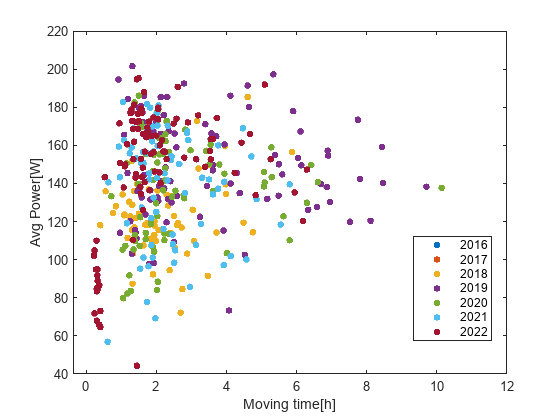

saveas(gcf,strcat('Figures/scatter_Power_Time_Year.png') )

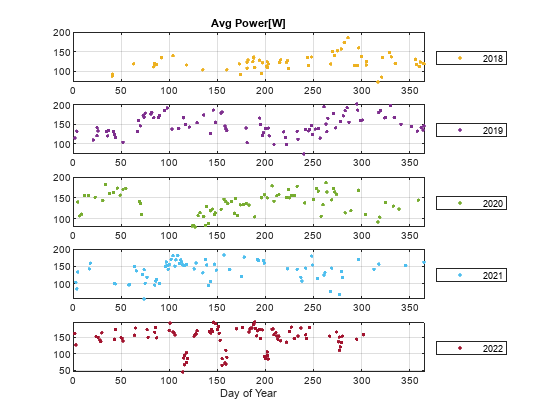

first = true;
figure
for year = 2018:2022
    subplot(5,1,year-2017)
    plot(cyclingData.DayofYear(cyclingData.Year==year,:), cyclingData.AverageWatts(cyclingData.Year==year,:), '.', color = def_colors(year-2015,:), Markersize=8)
    legend(num2str(year), Location="eastoutside")
    xlim([0 366])
    grid()
    if first
        title("Avg Power[W]")
        first=false;
    end
end
xlabel("Day of Year")
saveas(gcf,strcat('Figures/scatter_Power_Day_Year.png') )

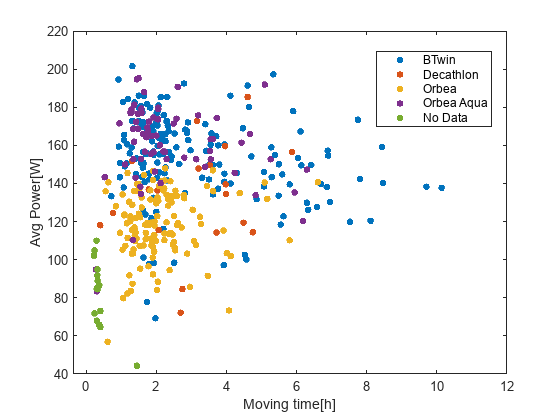


figure
gscatter(cyclingData.MovingTime./3600, cyclingData.AverageWatts, cyclingData.ActivityGear)
legend()
xlabel("Moving time[h]")
ylabel("Avg Power[W]")
saveas(gcf,strcat('Figures/scatter_Power_Time_Bike.png') )

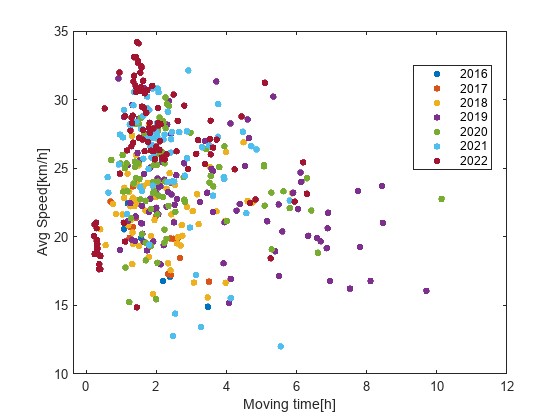

figure
gscatter(cyclingData.MovingTime./3600, cyclingData.MeanSpeed, cyclingData.Year)
legend()
xlabel("Moving time[h]")
ylabel("Avg Speed[km/h]")
saveas(gcf,strcat('Figures/scatter_Speed_Time_Year.png') )

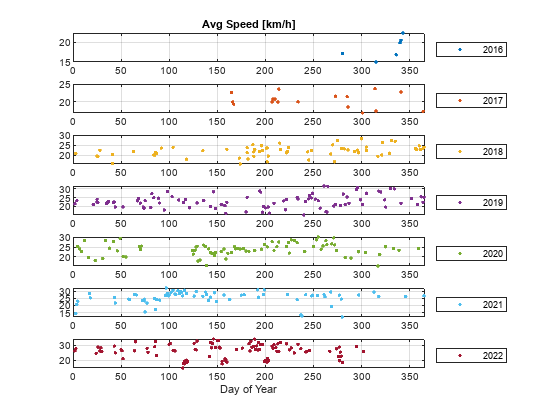


first = true;
figure
for year = 2016:2022
    subplot(7,1,year-2015)
    plot(cyclingData.DayofYear(cyclingData.Year==year,:), cyclingData.MeanSpeed(cyclingData.Year==year,:), '.', color = def_colors(year-2015,:), Markersize=8)
    legend(num2str(year), Location="eastoutside")
    xlim([0 366])
    grid()
    if first
        title("Avg Speed [km/h]")
        first=false;
    end
end
xlabel("Day of Year")
saveas(gcf,strcat('Figures/scatter_Speed_Day_Year.png') )

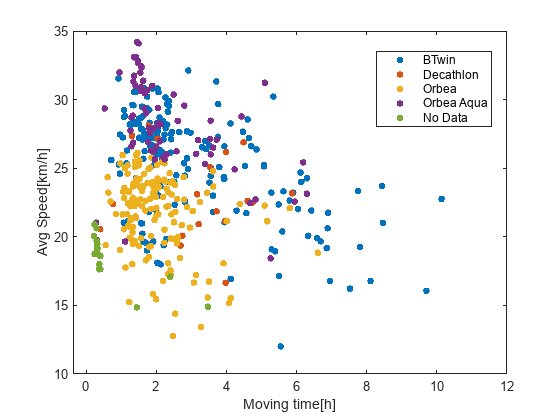


figure
gscatter(cyclingData.MovingTime./3600, cyclingData.MeanSpeed, cyclingData.ActivityGear)
legend()
xlabel("Moving time[h]")
ylabel("Avg Speed[km/h]")
saveas(gcf,strcat('Figures/scatter_Speed_Time_Bike.png') )

## ANOVA test on Power and Speed

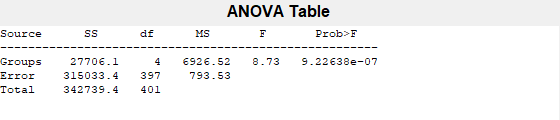

p = 9.2264e-07

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[2.7706e+04]}    {[  4]}    {[6.9265e+03]}    {[  8.7287]}    {[9.2264e-07]}
    {'Error' }    {[3.1503e+05]}    {[397]}    {[  793.5349]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[3.4274e+05]}    {[401]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {5×1 cell}
         n: [61 92 78 73 98]
    source: 'anova1'
     means: [122.6784 147.3893 137.2023 138.1264 146.0298]
        df: 397
         s: 28.1698


[p, tbl, stats] = anova1(cyclingData.AverageWatts, cyclingData.Year)

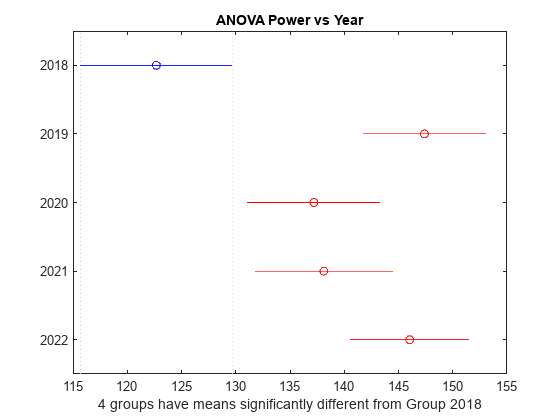

multcompare(stats);
title("ANOVA Power vs Year")

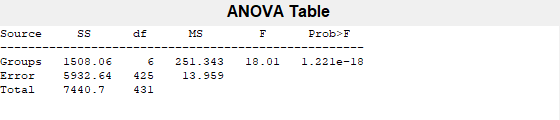

p = 1.2210e-18

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.5081e+03]}    {[  6]}    {[251.3427]}    {[ 18.0056]}    {[1.2210e-18]}
    {'Error' }    {[5.9326e+03]}    {[425]}    {[ 13.9592]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[7.4407e+03]}    {[431]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {7×1 cell}
         n: [6 17 65 93 80 73 98]
    source: 'anova1'
     means: [18.6100 20.3152 21.9577 22.9115 23.8483 25.5979 26.3331]
        df: 425
         s: 3.7362


saveas(gcf,strcat('Figures/ANOVA_Power_Year.png') )

[p, tbl, stats] = anova1(cyclingData.MeanSpeed, cyclingData.Year)

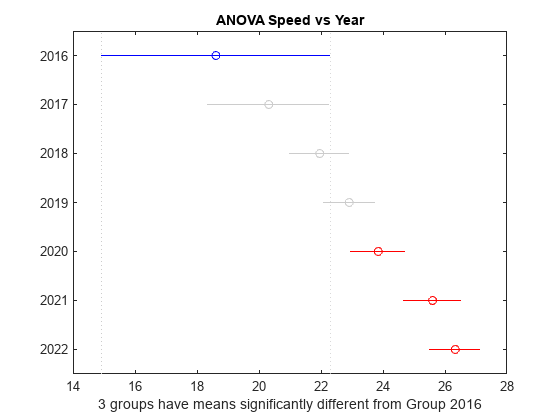

multcompare(stats);
title("ANOVA Speed vs Year")
saveas(gcf,strcat('Figures/ANOVA_Speed_Year.png') )

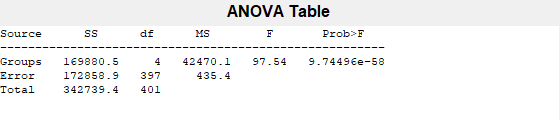

p = 9.7450e-58

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.6988e+05]}    {[  4]}    {[4.2470e+04]}    {[ 97.5399]}    {[9.7450e-58]}
    {'Error' }    {[1.7286e+05]}    {[397]}    {[  435.4129]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[3.4274e+05]}    {[401]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {5×1 cell}
         n: [172 19 128 67 16]
    source: 'anova1'
     means: [153.3552 133.3402 118.6049 160.0902 82.5680]
        df: 397
         s: 20.8665



[p, tbl, stats] = anova1(cyclingData.AverageWatts, cyclingData.ActivityGear)

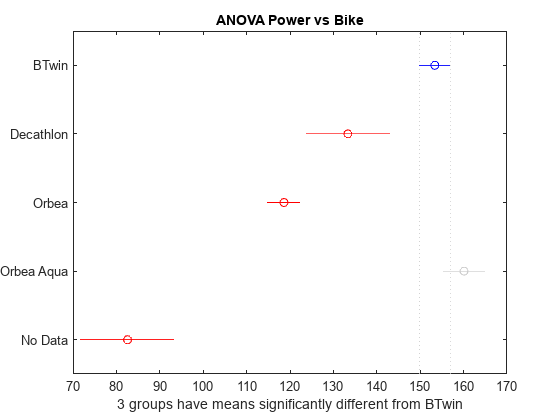

multcompare(stats);
title("ANOVA Power vs Bike")
saveas(gcf,strcat('Figures/ANOVA_Power_Bike.png') )

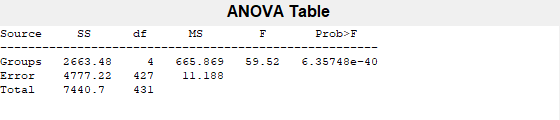

p = 6.3575e-40

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[2.6635e+03]}    {[  4]}    {[665.8692]}    {[ 59.5171]}    {[6.3575e-40]}
    {'Error' }    {[4.7772e+03]}    {[427]}    {[ 11.1879]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[7.4407e+03]}    {[431]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {5×1 cell}
         n: [173 19 155 67 18]
    source: 'anova1'
     means: [25.1768 23.1137 21.7259 28.0008 18.5484]
        df: 427
         s: 3.3448



[p, tbl, stats] = anova1(cyclingData.MeanSpeed, cyclingData.ActivityGear)

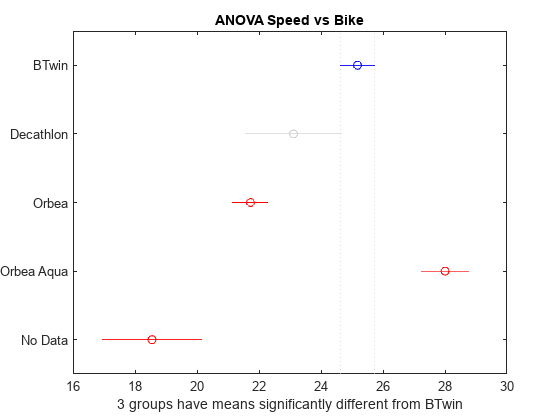

multcompare(stats);
title("ANOVA Speed vs Bike")

saveas(gcf,strcat('Figures/ANOVA_Speed_Bike.png') )

### Explanation of differences between Power and Speed

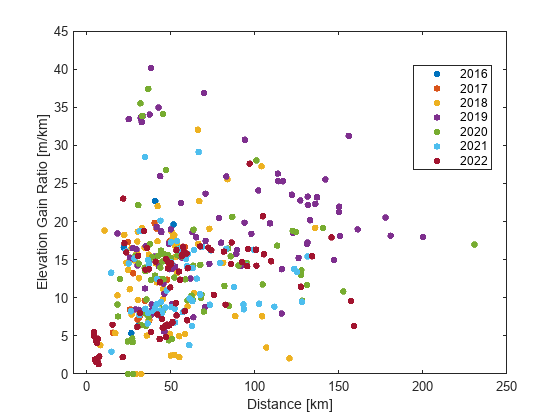

figure
gscatter(cyclingData.Distance, cyclingData.ElevationGainRatio, cyclingData.Year)
legend()
xlabel("Distance [km]")
ylabel("Elevation Gain Ratio [m/km]")
saveas(gcf,strcat('Figures/scatter_hilly_year.png'))

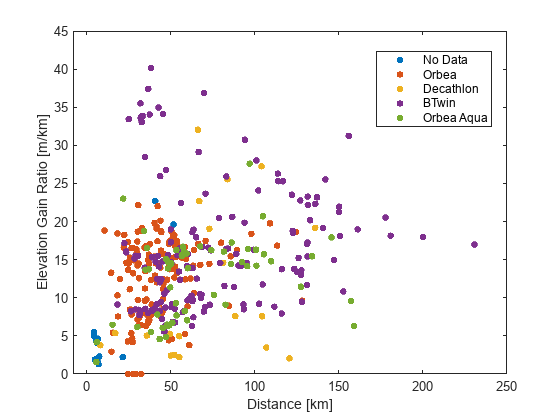

figure
gscatter(cyclingData.Distance, cyclingData.ElevationGainRatio, cyclingData.ActivityGear)
legend()
xlabel("Distance [km]")
ylabel("Elevation Gain Ratio [m/km]")
saveas(gcf,strcat('Figures/scatter_hilly_bike.png'))

## Regresion models

The aim is reproducing the Average Speed (directly related to **Moving Time**) and Average Watts (dorectly related to **Calories spent**)

% Check functional relation between variables
corr(cyclingData.Calories, cyclingData.MovingTime.*cyclingData.AverageWatts, 'rows','complete')

ans = 1.0000

Remove ID (not used), Moving Time, Calories (directly related to output) and ElevationGain (redundant) spent from tabel for regression

regression_vars = vars(vars~="ActivityID" & vars~="MovingTime" & vars~="Calories" & vars~="ElevationGain" ...
                       & vars~="MeanSpeed" & vars~="AverageWatts");

X = cyclingData(:,regression_vars)

X = 432×10 table
    Year    DayofYear    PausedTimeRatio    Distance    MaxSpeed    ElevationGainRatio    ElevationNet    ElevationHigh    TotalWeight    ActivityGear
    ____    _________    _______________    ________    ________    __________________    ____________    _____________    ___________    ____________

    2016       280          0.0075555        40.86       64.44            22.697              NaN            1701.8            85         {'No Data'} 
    2016       315            0.12576        51.73       47.88            19.621              NaN            1828.8            85         {'No Data'} 
    2016       336           0.084295 

xnames = X.Properties.VariableNames;
ySpeed = cyclingData(:,"MeanSpeed");
yPower = cyclingData(:,"AverageWatts");
idx_pow = ~isnan(yPower{:,:});

% Create indexes for cross-validation
idx = floor(1 + n_cvpartitions*rand(size(X,1),1));
err = zeros(n_cvpartitions,1);

Fill NaN values so methods don´t fail

X.MaxSpeed = fillmissing(X.MaxSpeed, "constant", mean(X.MaxSpeed,"omitnan"));
% X.ElevationGain = fillmissing(X.ElevationGain, "constant", 0);
X.ElevationGainRatio = fillmissing(X.ElevationGainRatio, "constant", 0);
X.ElevationNet = fillmissing(X.ElevationNet, "constant", 0);
X.ElevationHigh = fillmissing(X.ElevationHigh, "constant", 1000);

### Linear regression model

yPredict = zeros(size(ySpeed,1),1);
coeffs = zeros(1+size(X,2)+size(unique(X(:,1)),1)-3+size(unique(X(:,end)),1)-1,n_cvpartitions);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitlm([X(idx~=ii,:), ySpeed(idx~=ii,:)], "CategoricalVars", [1, size(X,2)]);
    yPredict(idx==ii,:) = predict(mdl, X(idx==ii,:));
    err(ii) = sqrt(mean( (table2array(ySpeed(idx==ii,:)) - yPredict(idx==ii,:)).^2 ));
    coeffs(:,ii) = mdl.Coefficients.Estimate;
end
rmse_Speed = mean(err)

rmse_Speed = 2.3948

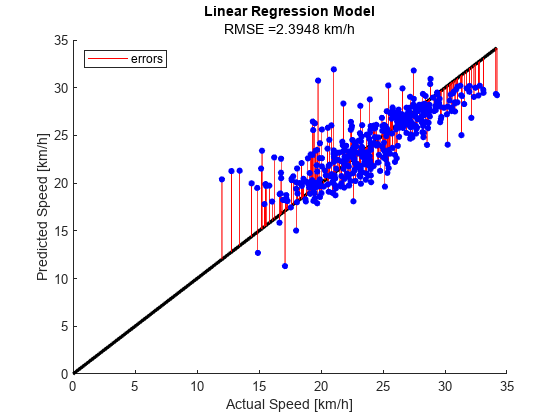


y_plot = table2array(ySpeed);
figure
hold on
plot([0, max(table2array(ySpeed))], [0, max(table2array(ySpeed))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Speed [km/h]')
ylabel('Predicted Speed [km/h]')
legend('','errors', 'Location', 'northwest')
title('Linear Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Speed), ' km/h'))
hold off
saveas(gcf,strcat('Figures/Regression_Linear_Speed.png') )

% Formula coeffs
mdl.Coefficients

ans = 19×4 table
                           Estimate          SE          tStat        pValue  
                          ___________    __________    _________    __________

    (Intercept)                37.542        6.3647       5.8984     8.373e-09
    Year_2017                 -1.6744        1.4427      -1.1606       0.24657
    Year_2018                -0.64279        1.3117     -0.49004        0.6244
    Year_2019                -0.53316        1.3433      -0.3969       0.69167
    Year_2020                -0.25903        1.3136     -0.19719       0.84379
    Year_2021                -0.30699         1.341     -0.22893       0.81905
    Year_2022                -0.81982        1.4336     -0.57187       0.56776
    Dayo

mean(coeffs,2)

ans =    34.4070
   -1.5064
   -0.3659
   -0.1002
    0.0213
   -0.1046
   -0.6613
    0.0003
   -0.7204
   -0.0111



yPredict = zeros(size(yPower,1),1);
coeffs = zeros(1+size(X,2)+size(unique(X(:,1)),1)-5+size(unique(X(:,end)),1)-1,n_cvpartitions);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitlm([X(idx~=ii & idx_pow,:), yPower(idx~=ii & idx_pow,:)], "CategoricalVars", [1, size(X,2)]);
    yPredict(idx==ii & idx_pow,:) = predict(mdl, X(idx==ii & idx_pow,:));
    err(ii) = sqrt(mean( (table2array(yPower(idx==ii & idx_pow,:)) - yPredict(idx==ii & idx_pow,:)).^2 ));
    coeffs(:,ii) = mdl.Coefficients.Estimate;
end
rmse_Power = mean(err)

rmse_Power = 19.0858

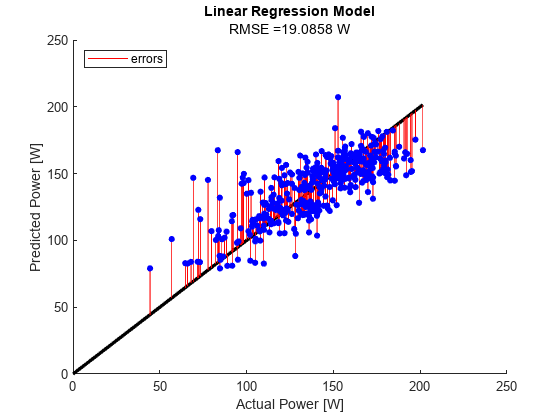


y_plot = table2array(yPower(idx_pow,:));
yPredict = yPredict(idx_pow,:);
figure
hold on
plot([0, max(table2array(yPower))], [0, max(table2array(yPower))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Power [W]')
ylabel('Predicted Power [W]')
legend('','errors', 'Location', 'northwest')
title('Linear Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Power), ' W'))
hold off
saveas(gcf,strcat('Figures/Regression_Linear_Power.png') )

% Formula coeffs
mdl.Coefficients

ans = 17×4 table
                               Estimate        SE         tStat        pValue  
                               _________    _________    ________    __________

    (Intercept)                   172.48       51.551      3.3458    0.00091046
    Year_2019                   -0.81059        4.497    -0.18025       0.85706
    Year_2020                    0.97858        4.253     0.23009       0.81815
    Year_2021                    -7.0534       4.7141     -1.4962       0.13551
    Year_2022                      2.523       7.3219     0.34458       0.73062
    DayofYear                  0.0035487     0.012183     0.29129         0.771
    PausedTimeRatio               -1.736       5.1101    -0.33973       0.73427
    

mean(coeffs,2)

ans =   163.2850
    0.4259
    0.4541
   -6.8489
    2.3664
    0.0035
   -6.4054
   -0.0167
    0.4956
    1.0862


#### Superlinear model

yPredict = zeros(size(yPower,1),1);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitlm([X(idx~=ii,:), ySpeed(idx~=ii,:)], 'interactions', "CategoricalVars", [1, size(X,2)]);
    yPredict(idx==ii,:) = predict(mdl, X(idx==ii,:));
    err(ii) = sqrt(mean( (table2array(ySpeed(idx==ii,:)) - yPredict(idx==ii,:)).^2 ));
end

rmse_Speed = mean(err)

rmse_Speed = 29.0329

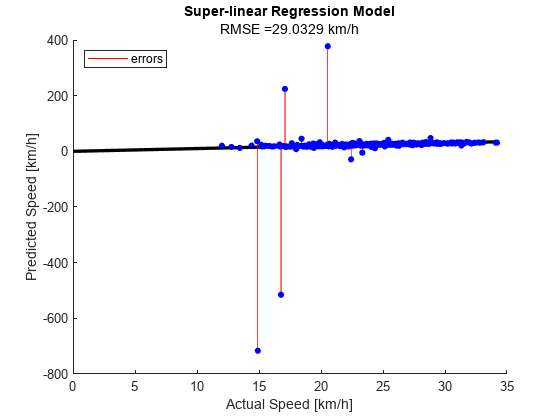


y_plot = table2array(ySpeed);
figure
hold on
plot([0, max(table2array(ySpeed))], [0, max(table2array(ySpeed))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Speed [km/h]')
ylabel('Predicted Speed [km/h]')
legend('','errors', 'Location', 'northwest')
title('Super-linear Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Speed), ' km/h'))
hold off
saveas(gcf,strcat('Figures/Regression_SupLinear_Speed.png') )


yPredict = zeros(size(yPower,1),1);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitlm([X(idx~=ii & idx_pow,:), yPower(idx~=ii & idx_pow,:)], 'interactions', "CategoricalVars", [1, size(X,2)]);
    yPredict(idx==ii & idx_pow,:) = predict(mdl, X(idx==ii & idx_pow,:));
    err(ii) = sqrt(mean( (table2array(yPower(idx==ii & idx_pow,:)) - yPredict(idx==ii & idx_pow,:)).^2 ));
end

rmse_Power = mean(err)

rmse_Power = 28.8106

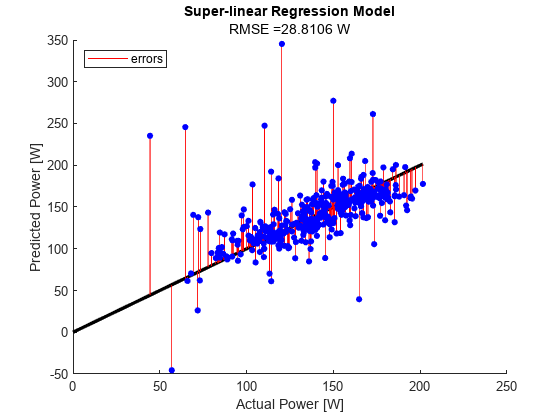


y_plot = table2array(yPower(idx_pow,:));
yPredict = yPredict(idx_pow,:);
figure
hold on
plot([0, max(table2array(yPower))], [0, max(table2array(yPower))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Power [W]')
ylabel('Predicted Power [W]')
legend('','errors', 'Location', 'northwest')
title('Super-linear Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Power), ' W'))
hold off
saveas(gcf,strcat('Figures/Regression_SupLinear_Power.png') )

### Non-parametric Regression Models

#### Support Vector Machine

yPredict = zeros(size(yPower,1),1);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitrsvm( X(idx~=ii,:), ySpeed(idx~=ii,:), "Standardize", true);
    yPredict(idx==ii,:) = predict(mdl, X(idx==ii,:));
    err(ii) = sqrt(mean( (table2array(ySpeed(idx==ii,:)) - yPredict(idx==ii,:)).^2 ));
end
rmse_Speed = mean(err)

rmse_Speed = 2.3915

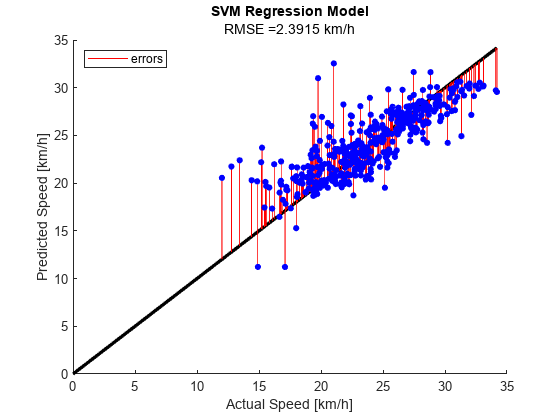


y_plot = table2array(ySpeed);
figure
hold on
plot([0, max(table2array(ySpeed))], [0, max(table2array(ySpeed))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Speed [km/h]')
ylabel('Predicted Speed [km/h]')
legend('','errors', 'Location', 'northwest')
title('SVM Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Speed), ' km/h'))
hold off
saveas(gcf,strcat('Figures/Regression_SVM_Speed.png') )


yPredict = zeros(size(yPower,1),1);
% Manual cross validation
for ii=1:n_cvpartitions
    mdl = fitrsvm( X(idx~=ii & idx_pow,:), yPower(idx~=ii & idx_pow,:), "Standardize", true);
    yPredict(idx==ii & idx_pow,:) = predict(mdl, X(idx==ii & idx_pow,:));
    err(ii) = sqrt(mean( (table2array(yPower(idx==ii & idx_pow,:)) - yPredict(idx==ii & idx_pow,:)).^2 ));
end
rmse_Power = mean(err)

rmse_Power = 20.7336

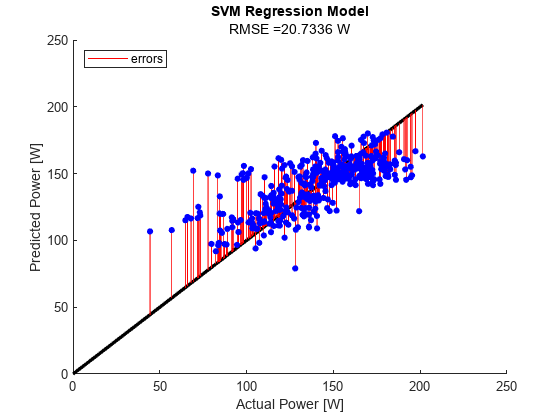


y_plot = table2array(yPower(idx_pow,:));
yPredict = yPredict(idx_pow,:);
figure
hold on
plot([0, max(table2array(yPower))], [0, max(table2array(yPower))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Power [W]')
ylabel('Predicted Power [W]')
legend('','errors', 'Location', 'northwest')
title('SVM Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Power), ' W'))
hold off
saveas(gcf,strcat('Figures/Regression_SVM_Power.png') )

#### Regression Tree

mdl = fitrtree(X, ySpeed, "CategoricalPredictors", [1, size(X,2)], 'Kfold', n_cvpartitions);
yPredict = kfoldPredict(mdl);
rmse_Speed = sqrt(kfoldLoss(mdl))

rmse_Speed = 2.6334

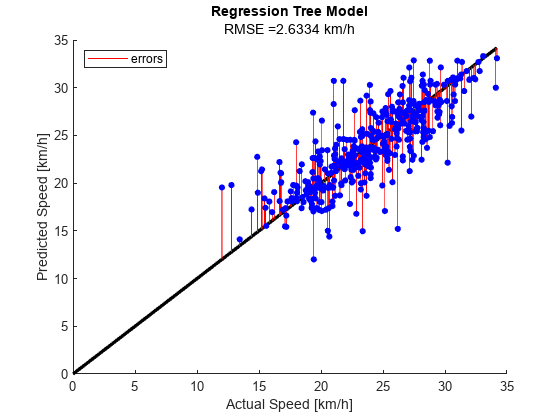


y_plot = table2array(ySpeed);
figure
hold on
plot([0, max(table2array(ySpeed))], [0, max(table2array(ySpeed))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Speed [km/h]')
ylabel('Predicted Speed [km/h]')
legend('','errors', 'Location', 'northwest')
title('Regression Tree Model')
subtitle(strcat('RMSE = ', num2str(rmse_Speed), ' km/h'))
hold off
saveas(gcf,strcat('Figures/Regression_Tree_Speed.png') )

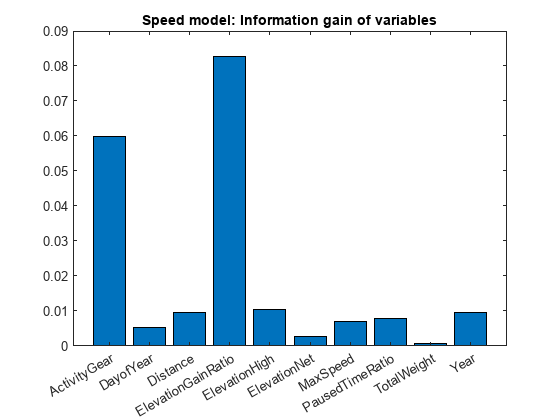


importance = zeros(mdl.KFold,size(mdl.X,2));
for ii = 1:mdl.KFold
    importance(ii,:) = predictorImportance(mdl.Trained{ii,1});
end
figure
bar(categorical(X.Properties.VariableNames), mean(importance,1))
title('Speed model: Information gain of variables')
saveas(gcf,strcat('Figures/Regression_Tree_Speed_varImportance.png') )


mdl = fitrtree(X(idx_pow,:), yPower(idx_pow,:), "CategoricalPredictors", [1, size(X,2)], 'Kfold', n_cvpartitions);
yPredict = kfoldPredict(mdl);
rmse_Power = sqrt(kfoldLoss(mdl))

rmse_Power = 20.9488

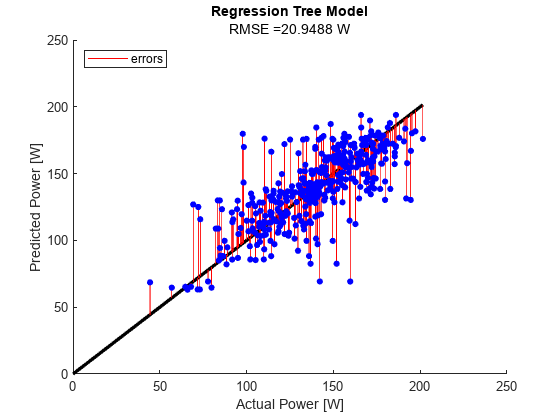


y_plot = table2array(yPower(idx_pow,:));
figure
hold on
plot([0, max(table2array(yPower))], [0, max(table2array(yPower))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Power [W]')
ylabel('Predicted Power [W]')
legend('','errors', 'Location', 'northwest')
title('Regression Tree Model')
subtitle(strcat('RMSE = ', num2str(rmse_Power), ' W'))
hold off
saveas(gcf,strcat('Figures/Regression_Tree_Power.png') )

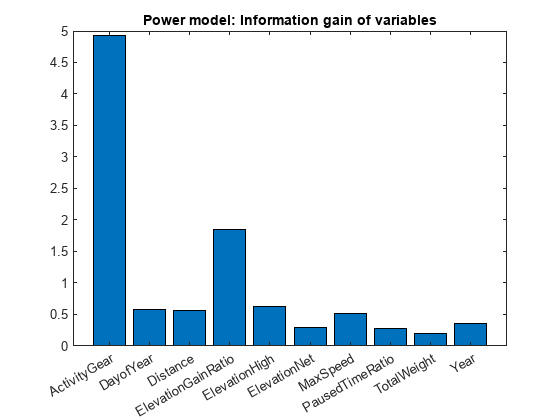


importance = zeros(mdl.KFold,size(mdl.X,2));
for ii = 1:mdl.KFold
    importance(ii,:) = predictorImportance(mdl.Trained{ii,1});
end
figure
bar(categorical(X.Properties.VariableNames), mean(importance,1))
title('Power model: Information gain of variables')
saveas(gcf,strcat('Figures/Regression_Tree_Power_varImportance.png') )

#### Gaussian Process Regression

mdl = fitrgp(X, ySpeed, "CategoricalPredictors", [1, size(X,2)], 'Kfold', n_cvpartitions, Standardize=true);
yPredict = kfoldPredict(mdl);
rmse_Speed = sqrt(kfoldLoss(mdl))

rmse_Speed = 2.0216

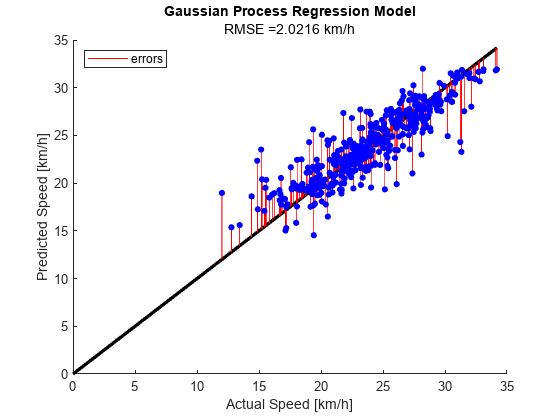


y_plot = table2array(ySpeed);
figure
hold on
plot([0, max(table2array(ySpeed))], [0, max(table2array(ySpeed))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Speed [km/h]')
ylabel('Predicted Speed [km/h]')
legend('','errors', 'Location', 'northwest')
title('Gaussian Process Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Speed), ' km/h'))
hold off
saveas(gcf,strcat('Figures/Regression_Gaussian_Speed.png') )


mdl = fitrgp(X(idx_pow,:), yPower(idx_pow,:), "CategoricalPredictors", [1, size(X,2)], 'Kfold', n_cvpartitions, Standardize=true);
yPredict = kfoldPredict(mdl);
rmse_Power = sqrt(kfoldLoss(mdl))

rmse_Power = 17.6801

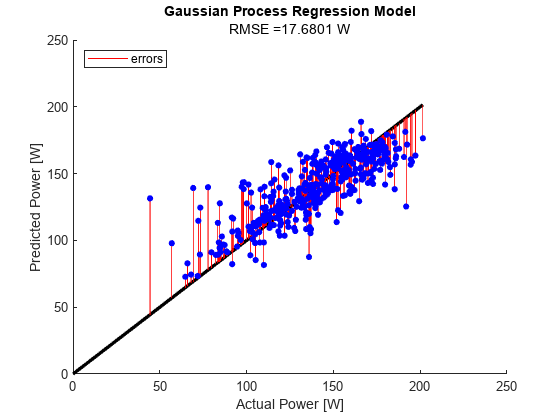


y_plot = table2array(yPower(idx_pow,:));
figure
hold on
plot([0, max(table2array(yPower))], [0, max(table2array(yPower))], 'k', LineWidth=2.5)
for ii = 1:size(y_plot)
    plot([y_plot(ii), y_plot(ii)], [y_plot(ii), yPredict(ii)], 'r-', LineWidth=0.15)
end
plot(y_plot, yPredict, 'b.', MarkerSize=16)
xlabel('Actual Power [W]')
ylabel('Predicted Power [W]')
legend('','errors', 'Location', 'northwest')
title('Gaussian Process Regression Model')
subtitle(strcat('RMSE = ', num2str(rmse_Power), ' W'))
hold off
saveas(gcf,strcat('Figures/Regression_Gaussian_Power.png') )